# Generate Signals in MATLAB

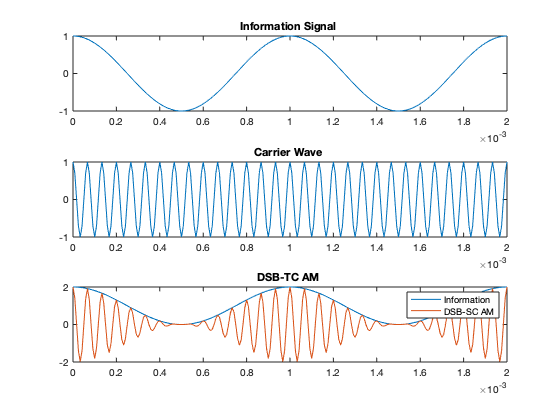

Ai = 1; % information amplitude
fi = 1000; % information frequency
Ac = 1; % carrier amplitude
fc = 15000; % information frequency
fs = 120000; % sampling frequency
Ao = 1; % DC offset
m = Ai/Ao; % AM modulation index

% generate time vector
t = [0 : 1/ fs: 0.002 ]; % [ start : step : end ]
% generate sine wave
si = Ai*cos(2*pi*fi*t);
sc = Ac*cos(2*pi*fc*t);
%sam = (Ao+Ai*cos(2*pi*fi*t)).*(Ac*cos(2*pi*fc*t));
sam = (Ao*Ac*cos(2*pi*fc*t)) + (m*Ao*Ac)*(cos(2*pi*(fc-fi)*t)/2 + cos(2*pi*(fc+fi)*t)/2);
% plot signal
subplot(3,1,1);
plot (t, si);
title ([ 'Information Signal ']);
subplot(3,1,2);
plot (t, sc);
title ([ 'Carrier Wave ']);
si = Ao + Ai*cos(2*pi*fi*t);
subplot(3,1,3);
plot (t, si);
hold on
plot (t, sam);
title ([ 'DSB-TC AM ']);
legend('Information','DSB-SC AM')

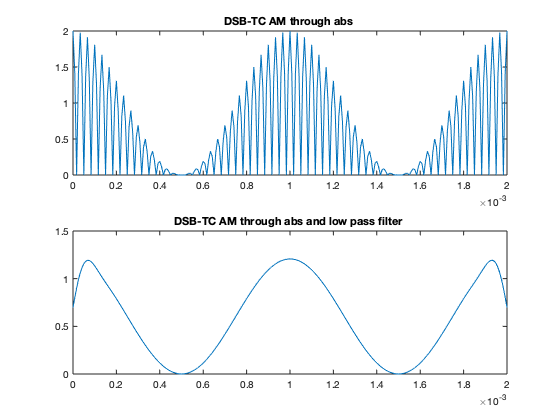


% demodulate
t = [0 : 1/ fs: 0.002 ];
abssam = abs(sam);
saml = lowpass(abssam,fi,fs);
figure()
subplot(2,1,1);
plot (t, abssam);
title ([ 'DSB-TC AM through abs ']);
subplot(2,1,2);
plot (t, saml);
title ([ 'DSB-TC AM through abs and low pass filter ']);